# NSOLT Network Gallery

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2020a

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2020, Shogo MURAMATSU, All rights reserved.

## Bivariate lattice-structure oversampled filter banks 

As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【Example】For $P/2=3$, a parametric orthonormal matrix $\mathbf{U}(\mathbf{\theta},\mathbf{\mu})$ can be constructed by 

        
$$\mathbf{U}(\mathbf{\theta},\mathbf{\mu}) \colon = \left(\begin{array}{cc} \mu_1 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right)
%
\left(\begin{array}{ccc} 
 1 & 0 & 0 \\
0 & \cos\theta_2& -\sin\theta_2 \\ 
0 & \sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & -\sin\theta_1  \\ 
 0 & 1 & 0 \\
\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_0& -\sin\theta_0 & 0 \\ 
\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right),$$


        
$${\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & \sin\theta_1  \\ 
 0 & 1 & 0 \\
-\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right),$$


where $\mathbf{\theta}\in\mathbb{R}^{(P-2)P/8}$ and $\mathbf{\mu}=\{-1,1\}^{P/2}$. For the sake of simplification, the sign parameters $\mu_k$ are fixed to $-1$for $\mathbf{U}_n^{\{d\}}$ witn odd $n$, otherwise they are fixed to $+1$.

Partial differentiation can be, for examle, conducted as

        
$$\frac{\partial}{\partial \theta_1}{\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
-\sin\theta_1& 0 & \cos\theta_1  \\ 
 0 & 0 & 0 \\
-\cos\theta_1 & 0 &  -\sin\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right).$$


### Definition of custom layers and networks 

Use a custom layer of Deep Learning Toolbox to implement Synthesis NSOLT (Synthesis NSOLT).

#### Definition of layers w/ Learnable properties

- Final rotation: $\mathbf{V}_0^T$ (saivdr.dcnn.nsoltFinalRotationLayer)

- Intermediate rotation: ${\mathbf{V}_n^{\{d\}}}^T$ (saivdr.dcnn.nsoltIntermediateRotationLayer)

#### Definition of layers w/o Learnable properties

- Bivariate inverese DCT (2-D IDCT): $\mathbf{E}_0^T=\mathbf{E}_0^{-1}$ (saivdr.dcnn.nsoltBlockDctLayer)

- Vertical up extension: $\mathbf{Q}^T(z_\mathrm{v}^{-1})$ (saivdr.dcnn.nsoltAtomExtensionLayer)

- Vertical down extension: $\bar{\mathbf{Q}}^T(z_\mathrm{v}^{-1})$  (saivdr.dcnn.nsoltAtomExtensionLayer)

- Horizontal left extension: $\mathbf{Q}^T(z_\mathrm{h}^{-1})$ (saivdr.dcnn.nsoltAtomExtensionLayer)

- Horizontal right extension: $\bar{\mathbf{Q}}^T(z_\mathrm{h}^{-1})$ (saivdr.dcnn.nsoltAtomExtensionLayer)

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

## Uniform decomposition for 2-D Grayscale image

% Decimation factor (Strides)
decFactors = [4 4]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [10 10]; % [Ps Pa] (Ps=Pa)

% No DC-leakage
noDcLeakage = true;

## Construction of layers

import saivdr.dcnn.*
analysisNsoltLayers = [
    imageInputLayer(szPatchTrn,...
        'Name','input','Normalization','none')
        
    nsoltBlockDct2dLayer('Name','E0',...
        'DecimationFactor',decFactors)
    nsoltInitialRotation2dLayer('Name','V0',...
        'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
        'NoDcLeakage',noDcLeakage)
        
    nsoltAtomExtension2dLayer('Name','Qh1rl',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vh1',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh2lu',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')

    nsoltAtomExtension2dLayer('Name','Qv1dl',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vv1',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv2uu',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')

    ]

analysisNsoltLayers =   次の層をもつ 11x1 の Layer 配列:

     1   'input'   イメージの入力                                    16x16x1 イメージ
     2   'E0'      saivdr.dcnn.nsoltBlockDct2dLayer               Block DCT of size 4x4
     3   'V0'      saivdr.dcnn.nsoltInitialRotation2dLayer        NSOLT initial rotation (ps,pa) = (10,10), (mv,mh) = (4,4)
     4   'Qh1rl'   saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Lower Coefs. (ps,pa) = (10,10)
     5   'Vh1'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (10,10)
     6   'Qh2lu'   saivdr.dcnn.nsoltAtomExtension2dLayer          Left shift Upper Coefs. (ps,pa) = (10,10)
     7   'Vh2'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (10,10)
     8   'Qv1dl'   saivdr.dcnn.nsoltAtomExtension2dLayer          Down shift Lower Coefs. (ps,pa) = (10,10)
     9   'Vv1'     s

synthesisNsoltLayers = [
    imageInputLayer([szPatchTrn./decFactors sum(nChannels)],...
        'Name','subband images','Normalization','none')

    nsoltIntermediateRotation2dLayer('Name','Vv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qv2uu~',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv1dl~',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Lower')

    nsoltIntermediateRotation2dLayer('Name','Vh2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qh2lu~',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh1rl~',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Lower') 
        
    nsoltFinalRotation2dLayer('Name','V0~',...
        'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
        'NoDcLeakage',noDcLeakage)        
    nsoltBlockIdct2dLayer('Name','E0~',...
        'DecimationFactor',decFactors) 
    ]

synthesisNsoltLayers =   次の層をもつ 11x1 の Layer 配列:

     1   'subband images'   イメージの入力                                    4x4x20 イメージ
     2   'Vv2~'             saivdr.dcnn.nsoltIntermediateRotation2dLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (10,10)
     3   'Qv2uu~'           saivdr.dcnn.nsoltAtomExtension2dLayer          Down shift Upper Coefs. (ps,pa) = (10,10)
     4   'Vv1~'             saivdr.dcnn.nsoltIntermediateRotation2dLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (10,10)
     5   'Qv1dl~'           saivdr.dcnn.nsoltAtomExtension2dLayer          Up shift Lower Coefs. (ps,pa) = (10,10)
     6   'Vh2~'             saivdr.dcnn.nsoltIntermediateRotation2dLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (10,10)
     7   'Qh2lu~'           saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Upper Coefs. (ps,pa) = (10,10)
     8   'Vh1~'             saivdr.dcnn.nsoltIn

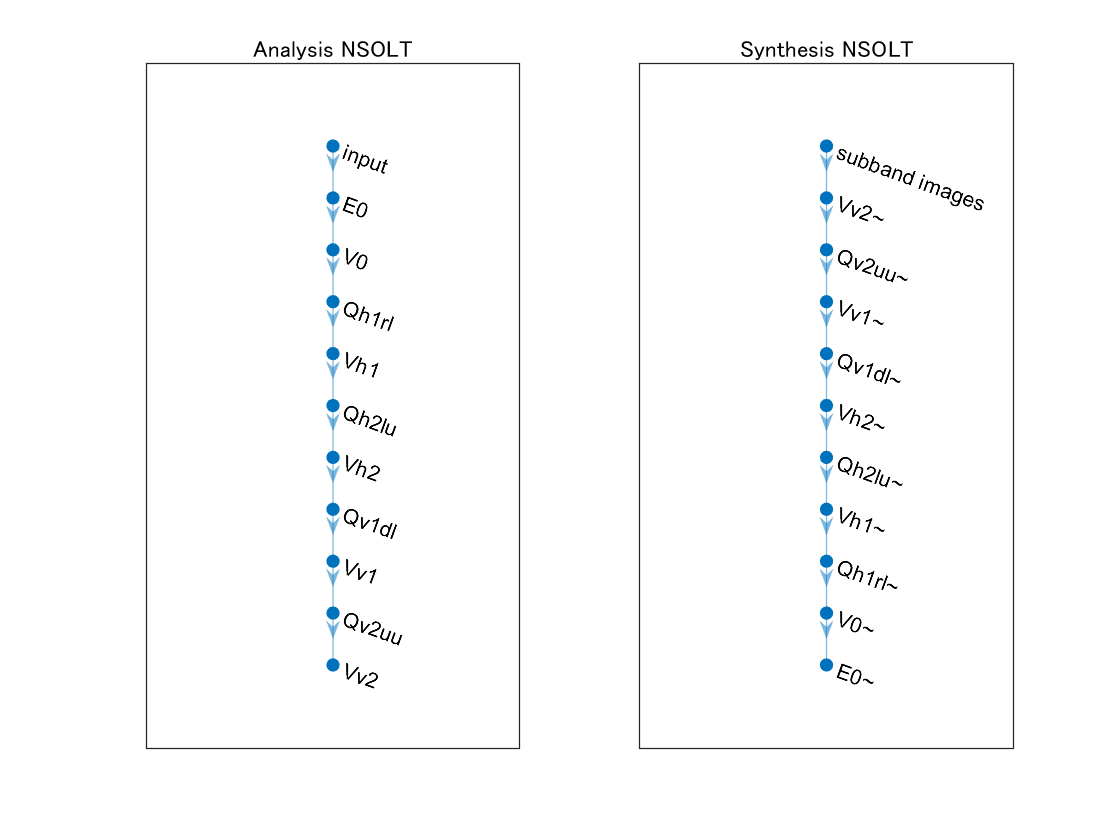

% Layer graph
analysislgraph = layerGraph(analysisNsoltLayers);
synthesislgraph = layerGraph(synthesisNsoltLayers);
figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

% Construction of deep learning network.
analysisnet = dlnetwork(analysislgraph);
synthesisnet = dlnetwork(synthesislgraph);
nLearnables = height(synthesisnet.Learnables);
for iLearnable = 1:nLearnables
    synthesisnet.Learnables.Value(iLearnable) = ...
    cellfun(@(x) x+pi/6*stdInitAng*randn(), ...
    synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
end
analysisnet = copyparameters(synthesisnet,analysisnet);

### Confirmation of perfect reconstruction

x = rand(szPatchTrn,'single');
dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
dls = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls);
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 6.1055e-12"



### Initial state of the atomic images

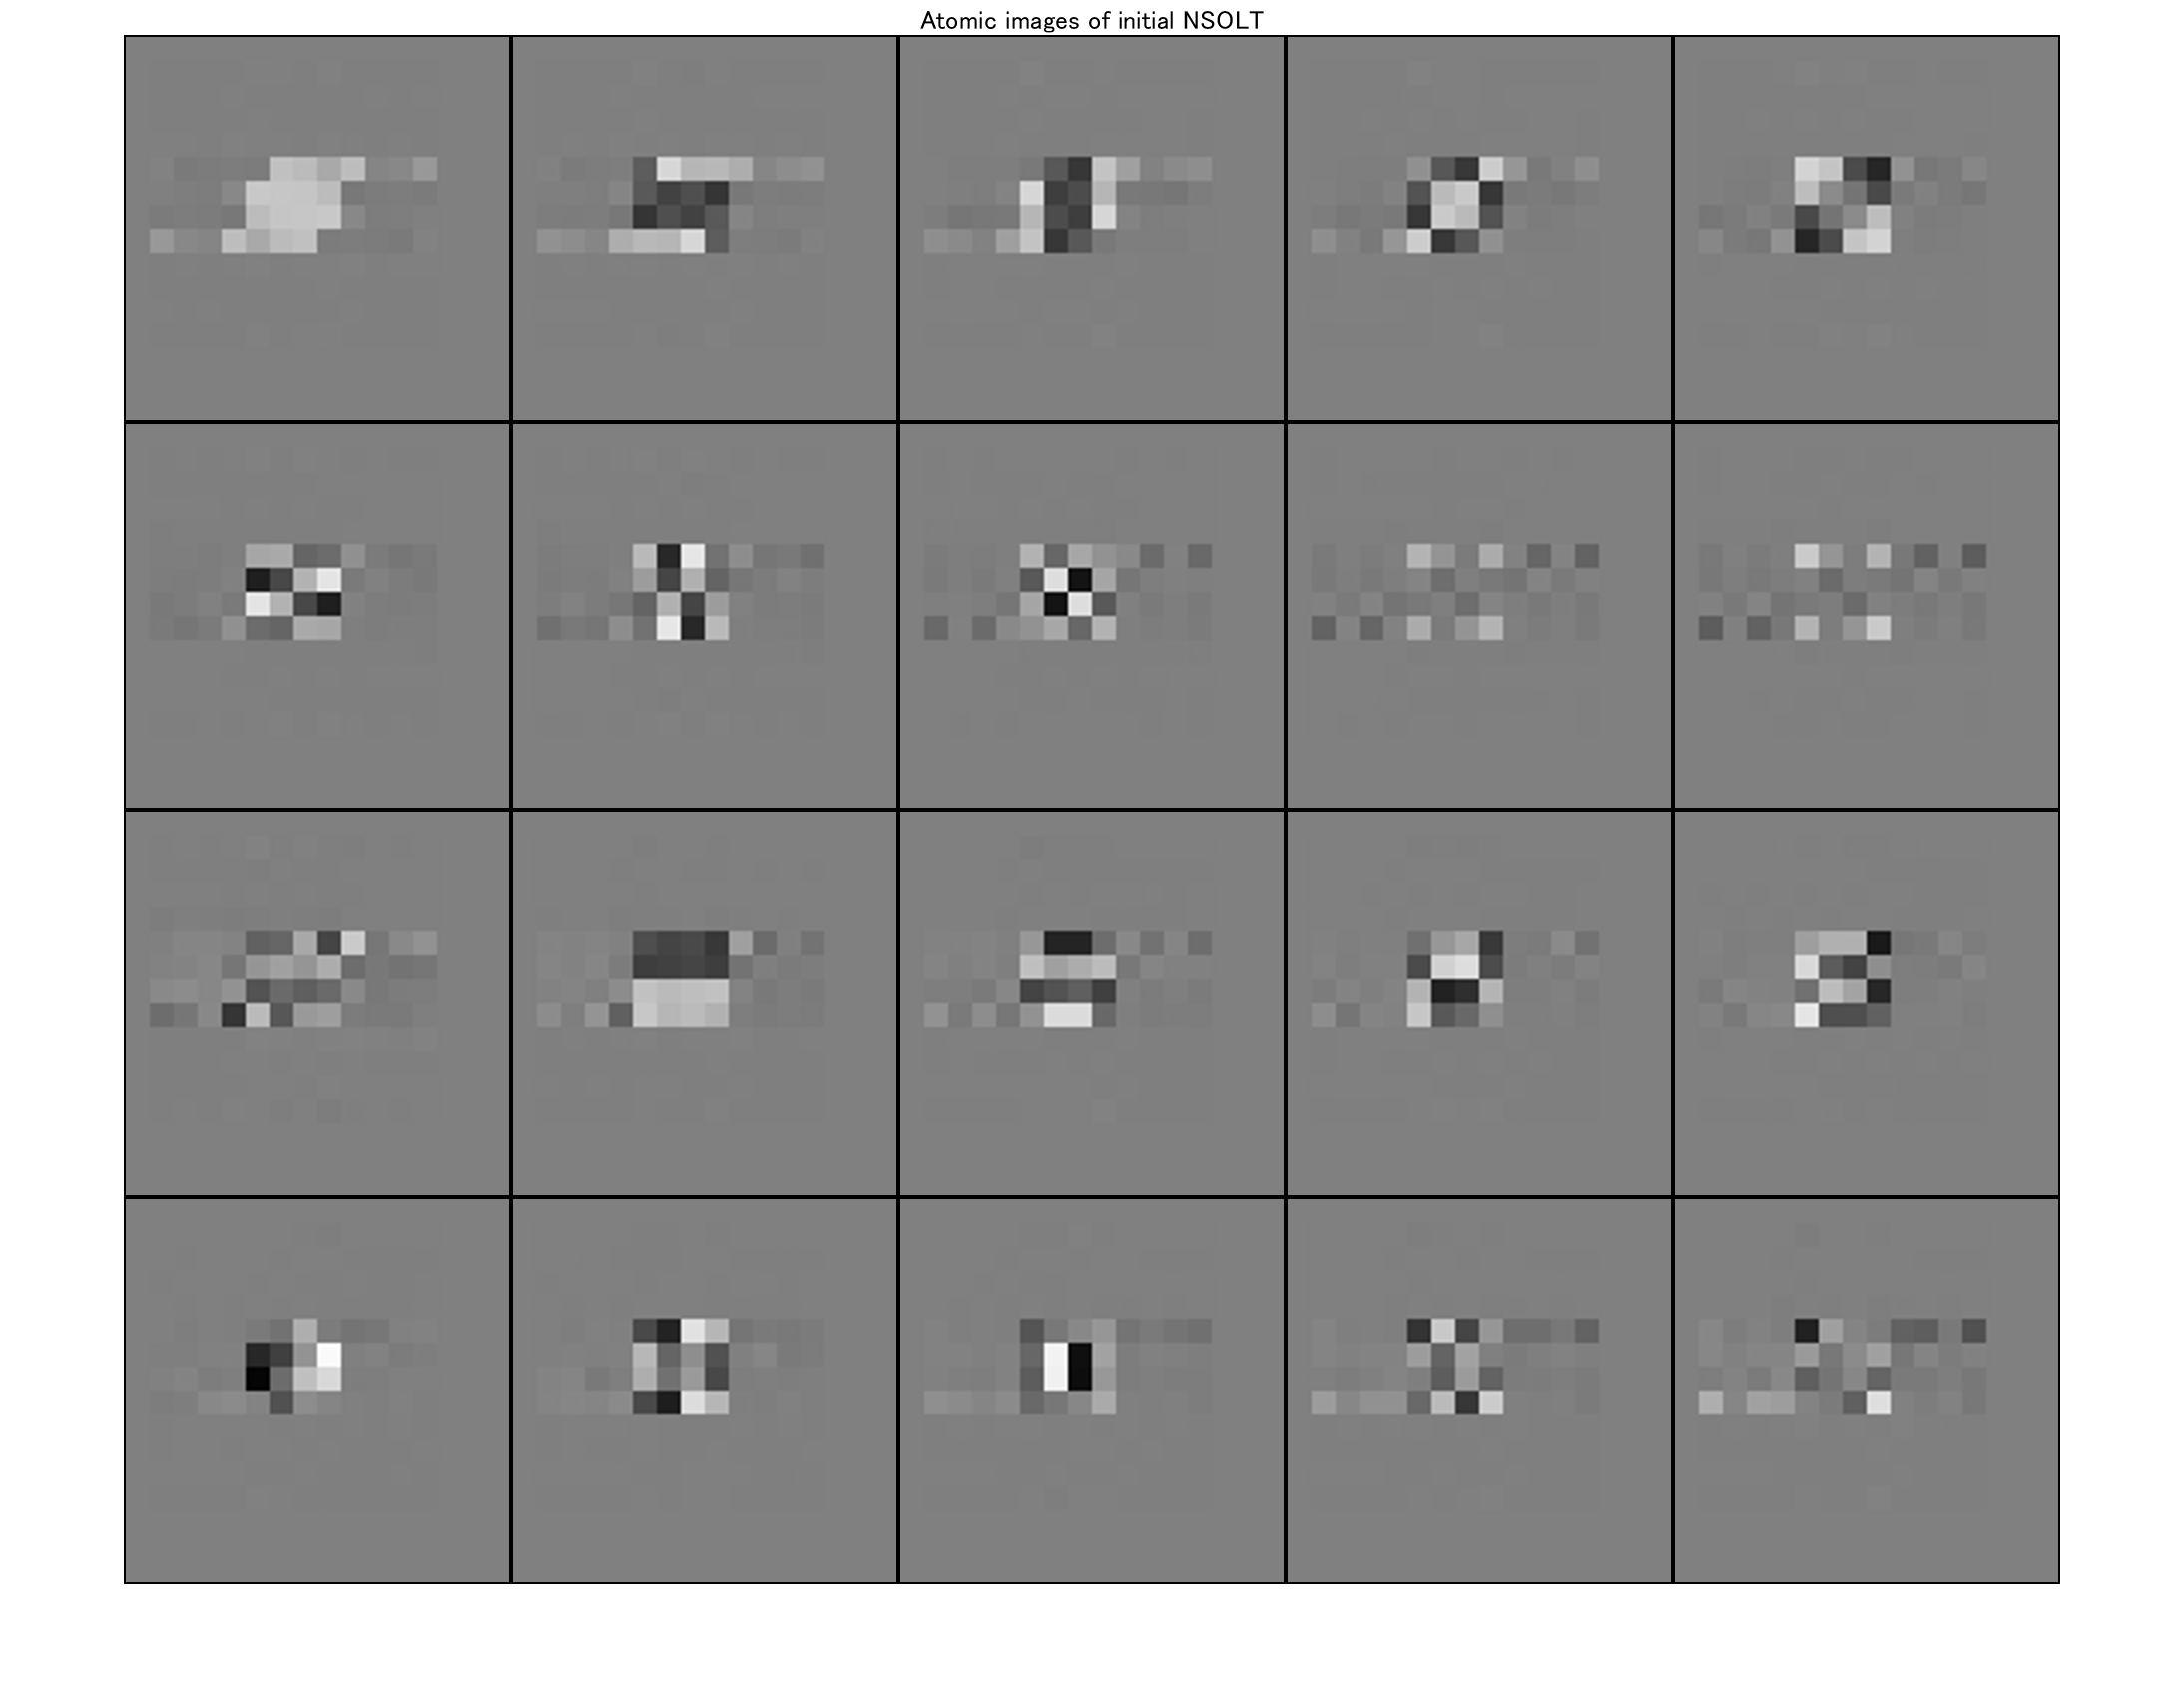

subbandImages = dlarray(zeros([szPatchTrn./decFactors sum(nChannels)],'single'),'SSC');
atomicImages = zeros([szPatchTrn 1 sum(nChannels)]);
for iAtom = 1:sum(nChannels)
    deltaImage = subbandImages;
    deltaImage(round(end/2),round(end/2),iAtom)  = 1;
    atomicImages(:,:,1,iAtom) = extractdata(synthesisnet.predict(deltaImage));
end
figure
mRows = 2^(nextpow2(sqrt(sum(nChannels)))-1);
mCols = ceil(sum(nChannels)/mRows);
montage(circshift(imresize(atomicImages,8,'nearest'),[8 8 0])+.5,...
    'Size',[mRows mCols],'BorderSize',[2 2])
title('Atomic images of initial NSOLT')

## Hierachical decomposition for 2-D Grayscale image

% Decimation factor (Strides)
decFactors = [2 2]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [4 4]; % [Ps Pa] (Ps=Pa)

% No DC-leakage
noDcLeakage = true;

## Construction of layers

import saivdr.dcnn.*
analysisNsoltLv1Layers = [
    imageInputLayer(szPatchTrn,...
    'Name','input','Normalization','none')
    
    nsoltBlockDct2dLayer('Name','E0Lv1',...
    'DecimationFactor',decFactors)
    nsoltInitialRotation2dLayer('Name','V0Lv1',...
    'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
    'NoDcLeakage',noDcLeakage)
    
    nsoltAtomExtension2dLayer('Name','Qh1rlLv1',...
    'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vh1Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh2luLv1',...
    'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh2Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis')
    
    nsoltAtomExtension2dLayer('Name','Qh3rlLv1',...
    'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vh3Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh4luLv1',...
    'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh4Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis')
    
    nsoltAtomExtension2dLayer('Name','Qv1dlLv1',...
    'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vv1Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv2uuLv1',...
    'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv2Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis')
    
    nsoltAtomExtension2dLayer('Name','Qv3dlLv1',...
    'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vv3Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv4uuLv1',...
    'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv4Lv1',...
    'NumberOfChannels',nChannels,'Mode','Analysis')
    
    nsoltChannelSeparation2dLayer('Name','SpLv1')
    
    ]

analysisNsoltLv1Layers =   次の層をもつ 20x1 の Layer 配列:

     1   'input'      イメージの入力                                    16x16x1 イメージ
     2   'E0Lv1'      saivdr.dcnn.nsoltBlockDct2dLayer               Block DCT of size 2x2
     3   'V0Lv1'      saivdr.dcnn.nsoltInitialRotation2dLayer        NSOLT initial rotation (ps,pa) = (4,4), (mv,mh) = (2,2)
     4   'Qh1rlLv1'   saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Lower Coefs. (ps,pa) = (4,4)
     5   'Vh1Lv1'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (4,4)
     6   'Qh2luLv1'   saivdr.dcnn.nsoltAtomExtension2dLayer          Left shift Upper Coefs. (ps,pa) = (4,4)
     7   'Vh2Lv1'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (4,4)
     8   'Qh3rlLv1'   saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Lower Coefs. (ps,pa) = (4,4)
    


analysisNsoltLv2Layers = [
        
    nsoltBlockDct2dLayer('Name','E0Lv2',...
        'DecimationFactor',decFactors)
    nsoltInitialRotation2dLayer('Name','V0Lv2',...
        'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
        'NoDcLeakage',noDcLeakage)
        
    nsoltAtomExtension2dLayer('Name','Qh1rlLv2',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vh1Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh2luLv2',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh2Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')

    nsoltAtomExtension2dLayer('Name','Qh3rlLv2',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vh3Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh4luLv2',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh4Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')        
 
    nsoltAtomExtension2dLayer('Name','Qv1dlLv2',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vv1Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv2uuLv2',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv2Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')

    nsoltAtomExtension2dLayer('Name','Qv3dlLv2',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vv3Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv4uuLv2',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv4Lv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')        
    
    ]

analysisNsoltLv2Layers =   次の層をもつ 18x1 の Layer 配列:

     1   'E0Lv2'      saivdr.dcnn.nsoltBlockDct2dLayer               Block DCT of size 2x2
     2   'V0Lv2'      saivdr.dcnn.nsoltInitialRotation2dLayer        NSOLT initial rotation (ps,pa) = (4,4), (mv,mh) = (2,2)
     3   'Qh1rlLv2'   saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Lower Coefs. (ps,pa) = (4,4)
     4   'Vh1Lv2'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (4,4)
     5   'Qh2luLv2'   saivdr.dcnn.nsoltAtomExtension2dLayer          Left shift Upper Coefs. (ps,pa) = (4,4)
     6   'Vh2Lv2'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (4,4)
     7   'Qh3rlLv2'   saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Lower Coefs. (ps,pa) = (4,4)
     8   'Vh3Lv2'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT in

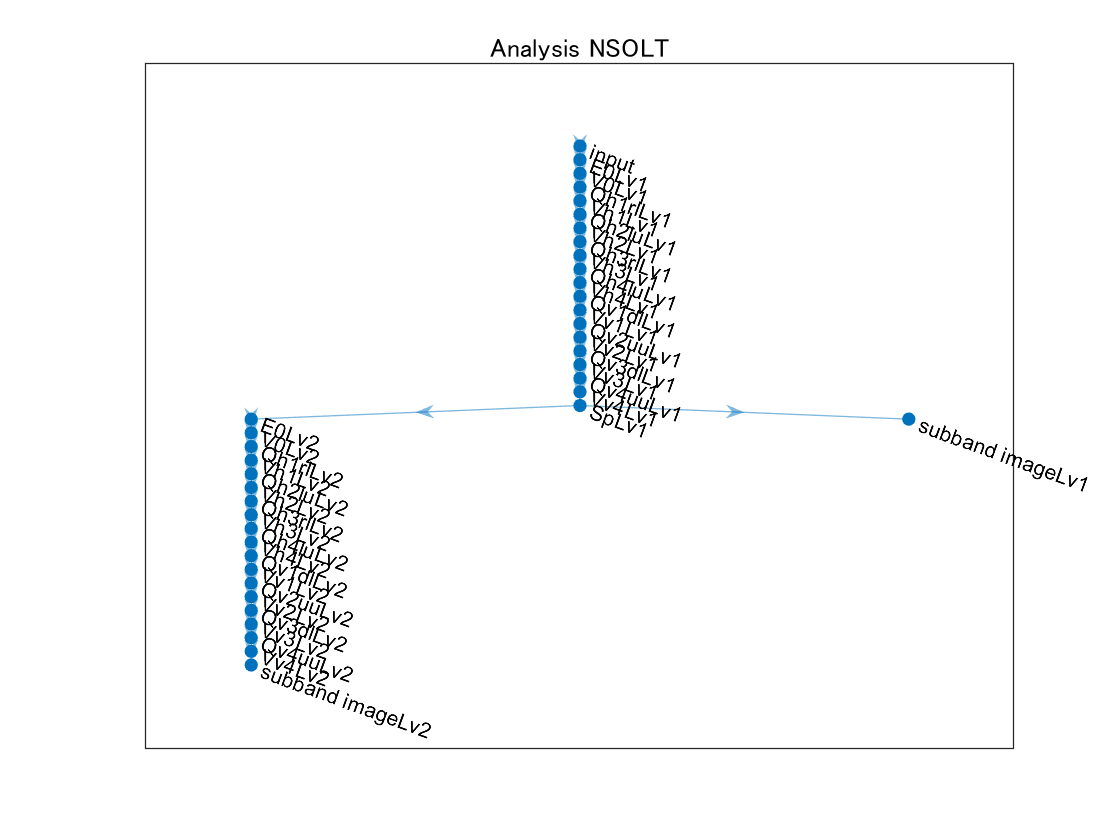


synthesisNsoltLv2Layers = [
    
    imageInputLayer([szPatchTrn./(decFactors.^2) sum(nChannels)],...
        'Name','subband imagesLv2','Normalization','none')

    nsoltIntermediateRotation2dLayer('Name','Vv4Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qv4uuLv2~',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv3Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv3dlLv2~',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Lower')        

    nsoltIntermediateRotation2dLayer('Name','Vv2Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qv2uuLv2~',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv1Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv1dlLv2~',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Lower')

    nsoltIntermediateRotation2dLayer('Name','Vh4Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qh4luLv2~',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh3Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh3rlLv2~',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Lower')        

    nsoltIntermediateRotation2dLayer('Name','Vh2Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qh2luLv2~',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh1Lv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh1rlLv2~',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Lower') 
        
    nsoltFinalRotation2dLayer('Name','V0Lv2~',...
        'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
        'NoDcLeakage',noDcLeakage)        
    nsoltBlockIdct2dLayer('Name','E0Lv2~',...
        'DecimationFactor',decFactors) 

    ];

synthesisNsoltLv1Layers = [
    
    imageInputLayer([szPatchTrn./decFactors (sum(nChannels)-1)],...
        'Name','subband imagesLv1','Normalization','none')
    
    nsoltChannelConcatenation2dLayer('Name','CnLv1')
        
    nsoltIntermediateRotation2dLayer('Name','Vv4Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qv4uuLv1~',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv3Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv3dlLv1~',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Lower')        

    nsoltIntermediateRotation2dLayer('Name','Vv2Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qv2uuLv1~',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv1Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv1dlLv1~',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Lower')

    nsoltIntermediateRotation2dLayer('Name','Vh4Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qh4luLv1~',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh3Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh3rlLv1~',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Lower')        

    nsoltIntermediateRotation2dLayer('Name','Vh2Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qh2luLv1~',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh1Lv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh1rlLv1~',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Lower') 
        
    nsoltFinalRotation2dLayer('Name','V0Lv1~',...
        'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
        'NoDcLeakage',noDcLeakage)        
    nsoltBlockIdct2dLayer('Name','E0Lv1~',...
        'DecimationFactor',decFactors) 
    ];

% Layer graph
analysislgraph = layerGraph(analysisNsoltLv1Layers);
analysislgraph = analysislgraph.addLayers(analysisNsoltLv2Layers);
analysislgraph = analysislgraph.connectLayers('SpLv1/out1','E0Lv2');
analysislgraph = analysislgraph.addLayers(regressionLayer('Name','subband imageLv1'));
analysislgraph = analysislgraph.connectLayers('SpLv1/out2','subband imageLv1');
analysislgraph = analysislgraph.addLayers(regressionLayer('Name','subband imageLv2'));
analysislgraph = analysislgraph.connectLayers('Vv4Lv2','subband imageLv2');

synthesislgraph = layerGraph(synthesisNsoltLv2Layers);
synthesislgraph = synthesislgraph.addLayers(synthesisNsoltLv1Layers);
synthesislgraph = synthesislgraph.disconnectLayers('subband imagesLv1','CnLv1/in1');
synthesislgraph = synthesislgraph.connectLayers('subband imagesLv1','CnLv1/in2');
synthesislgraph = synthesislgraph.connectLayers('E0Lv2~','CnLv1/in1');
synthesislgraph = synthesislgraph.addLayers(regressionLayer('Name','output'));
synthesislgraph = synthesislgraph.connectLayers('E0Lv1~','output');

figure
plot(analysislgraph)
title('Analysis NSOLT')

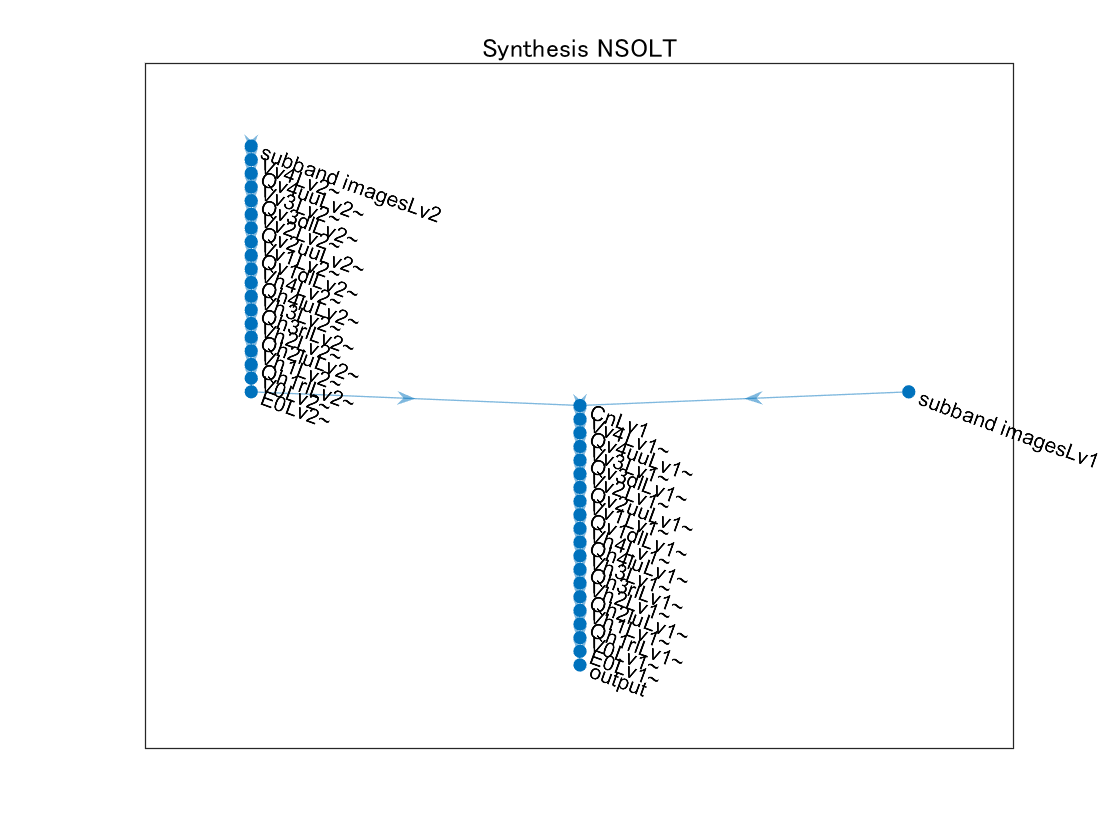

figure
plot(synthesislgraph)
title('Synthesis NSOLT')

### Setting up the analytical dictionary (adjoint operator)

Copying synthesis dictionary parameters to the analyisis dictionary (the adjoint operator)

function newanalysisnet = copyparameters(synthesisnet,oldanalysisnet)
newanalysisnet = oldanalysisnet;
analysisLearnables = oldanalysisnet.Learnables;
synthesisLearnables = synthesisnet.Learnables;
nLearnables = height(analysisLearnables);
for iLearnable = 1:nLearnables
    t = synthesisLearnables.Value(nLearnables-iLearnable+1);
    newanalysisnet.Learnables.Value(iLearnable) = t; 
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.